## MATLAB Initial Value Problems

In this livescript, you will learn how

- To solve first order initial value problems in MATLAB

We'll consider the solution of the initial value problem


$$\frac{dx}{dt}=\arctan{\{\sin^{2}{(x)}}\}$$


with the initial condition $x(0)=\pi/4$.

As always, it's always worh a shot to use $\texttt{dsolve}$ to see whether an analytical solution exists

syms x(t) a
eqn = diff(x,t) == atan(sin(x).^2);
init_cond = x(0)==pi/4;
dsolve(eqn,init_cond)

 
ans =
 
[ empty sym ]
 


Unfortunately, no analytical solution exists, but that shouldn't worry us as MATLAB has numerous numerical solvers for initial value problems including 

- $\texttt{ode45}
$        Uses Runge-Kutta method of orders 4 and 5

- $\texttt{ode23}
$        Uses Runge-Kutta method of orders 2 and 3

- $\texttt{ode23t }$    Uses the the Crank-Nicolson method

Many more solvers using more complicated algorithms that won't be covered in this course are

- 
$$\texttt{ode113}$$


- 
$$\texttt{ode15s}$$


- 
$$\texttt{ode23s}$$


- 
$$\texttt{ode23tb}$$


- 
$$\texttt{ode15i}$$


There are situations where each solver has better performance, but typically it's recommended to try $\texttt{ode45}
$ first.

Since each solver has the same syntax


$$\texttt{[t,x] = ode\_\_(odefun,tspan,x0)}$$


we'll just cover the use of $\texttt{ode45}
$.

The first input $\texttt{odefun}$ is a function handle that specifies our differential equation.

odefun = @(t,x) atan(sin(x).^2);

$\texttt{tspan}
$ defines the size of the time domain that we want to solve the IVP in, $\texttt{tspan = [ti tf]}$. To solve the IVP within the interval $0\leq t \leq 100$, we have

tspan = [0 100]

tspan =      0   100


$\texttt{x0}
$ is a vector of the initial conditions, which in our case is given by

x0 = pi/4;

With these pieces, we can then call $\texttt{ode45}
$ using the following command

[t,x] = ode45(odefun,tspan,x0);

Plotting the position and velocity, we find

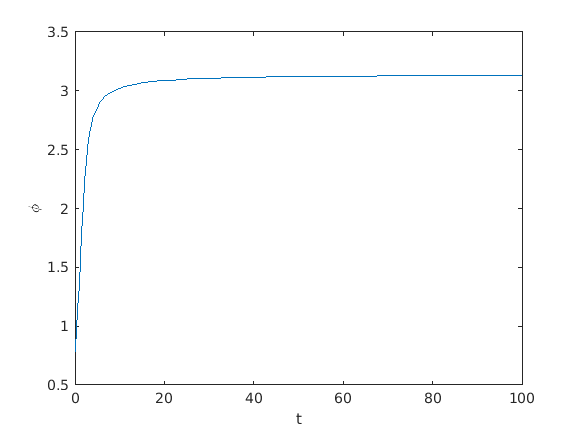

plot(t,x)
xlabel('t')
ylabel('x')
xlim([0,100])

(b)        Change the code to use $\texttt{ode23}
$ and $\texttt{ode23t}$ to solve the initial value problem.